# 自举开关的失真分析

## 导通电流的模型建立

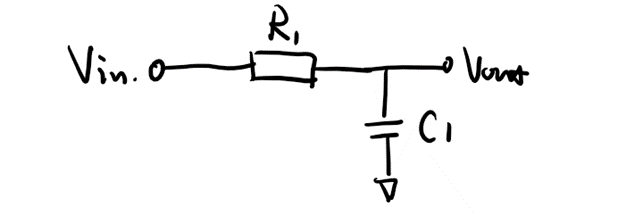

%% /////////////////////// Model for the Id of RC ///////////////////////
clc
clear
C1 = 38.72e-12;
Ron = 204;
tau = C1*Ron

tau = 7.8989e-09

Fs = 5E6;
Fin = 51/512*Fs;
win = Fin * 2 * pi;
V0 = 0.895;

timeoffset = 150e-9;
num = [C1, 0];
den = [tau, 1];
sys_id = tf(num, den)

sys_id =
 
    3.872e-11 s
  ---------------
  7.899e-09 s + 1
 
Continuous-time transfer function.



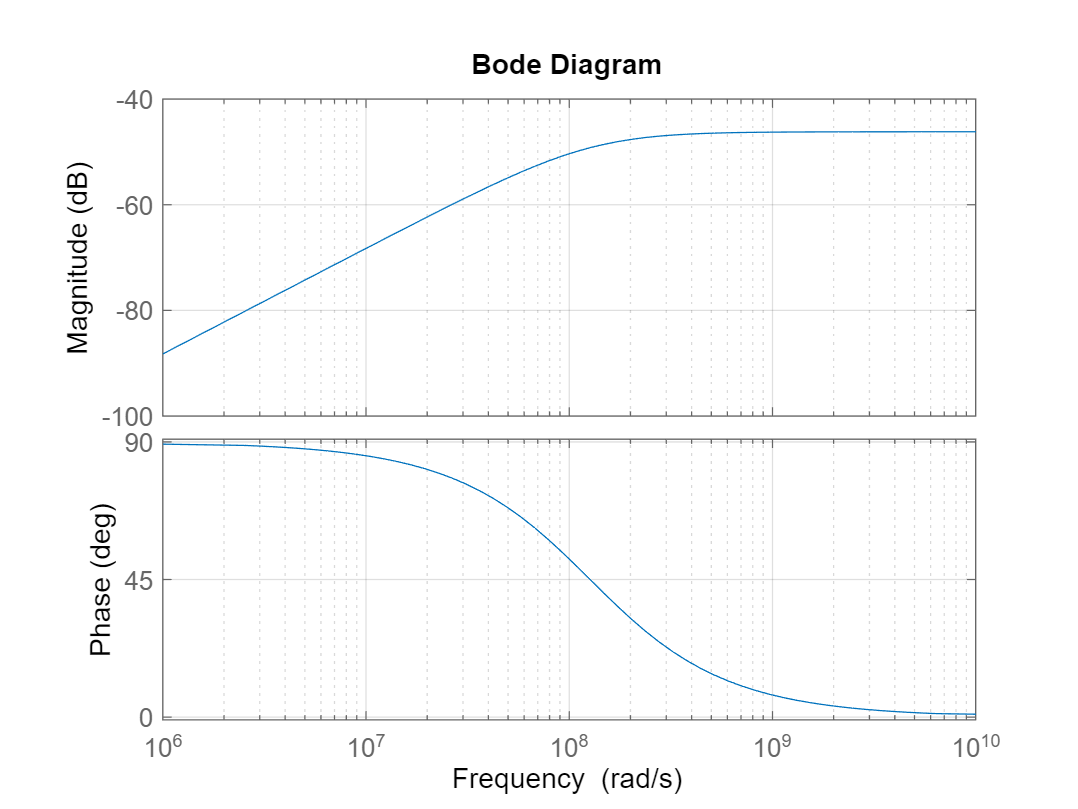

figure()            % Show the basic frequency response
bode(sys_id);
grid on;

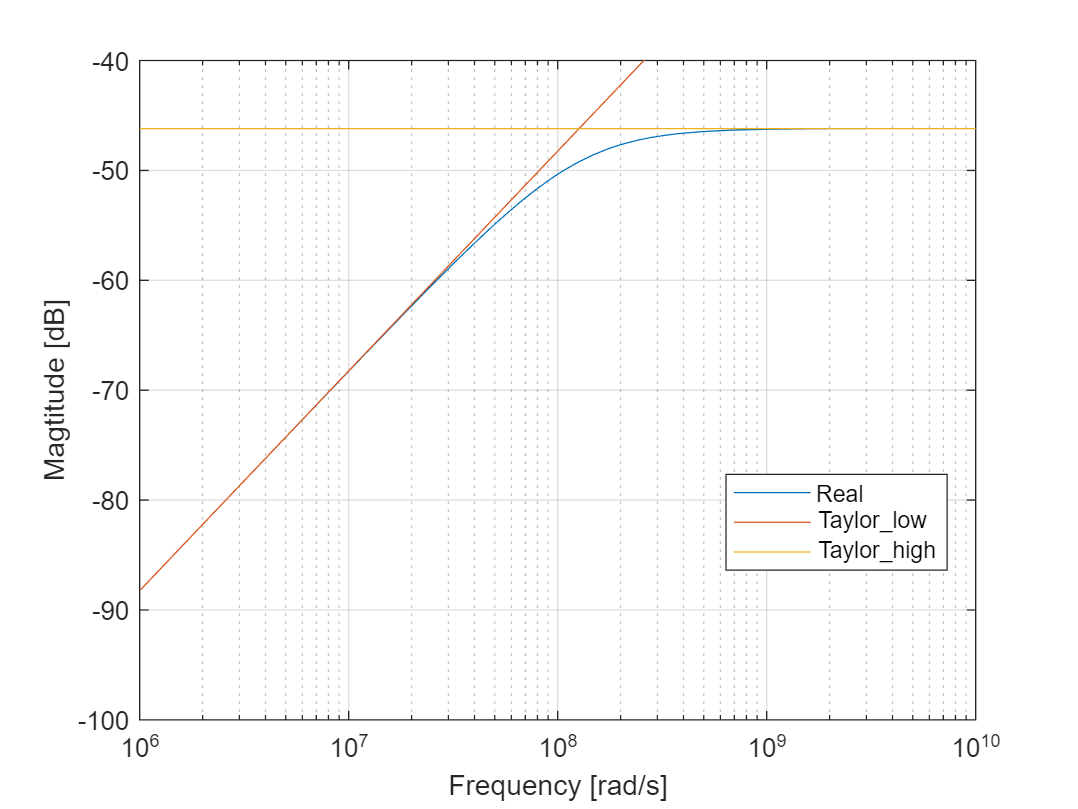

%% //////// Calculate the frequency response with Taylor Series /////////
[mag, phase, dw] = bode(sys_id);

mag_taylor_low = mag2db(dw.*C1);
mag_taylor_high = mag2db(ones(size(dw))./Ron);

phase_taylor_low = 90 - rad2deg(dw.*tau);

figure
semilogx(dw, [mag2db(mag(:,:))', mag_taylor_low, mag_taylor_high]);
% semilogx(dw, [mag_calculated, mag_taylor_low, mag_taylor_high,]);

grid on;
legend({'Real'; 'Taylor\_low'; 'Taylor\_high'; }, Location="best")
ylim([-100, -40])
xlabel("Frequency [rad/s]"); ylabel("Magtitude [dB]");

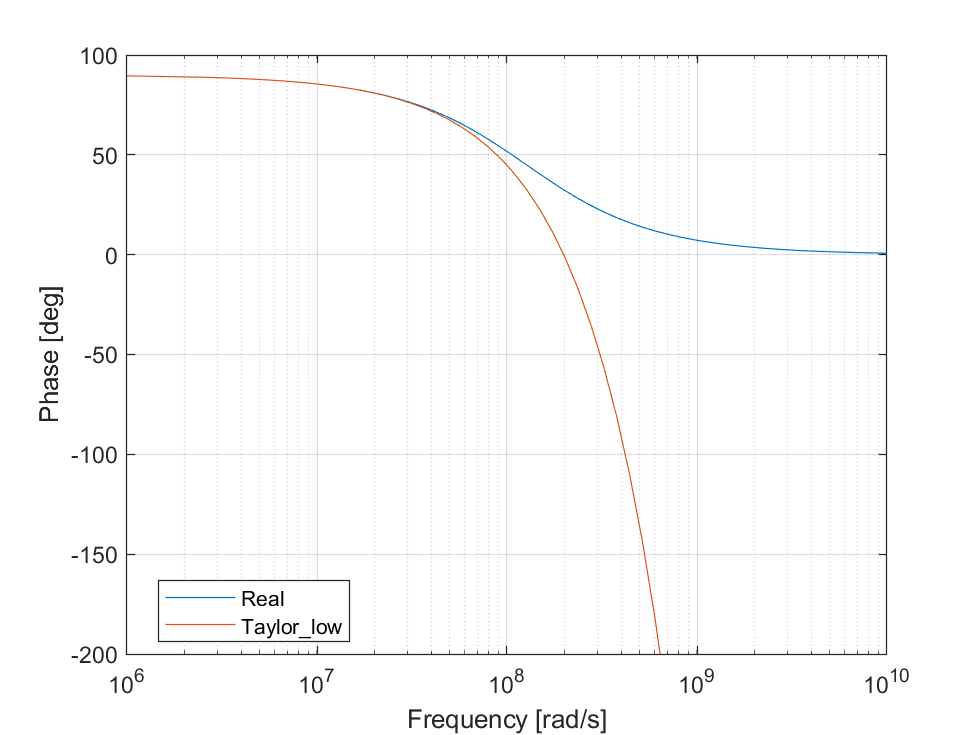

figure
semilogx(dw, [phase(:,:)', phase_taylor_low,]);
grid on;
legend({'Real'; 'Taylor\_low'; }, Location="best")
ylim([-200, 100])
xlabel("Frequency [rad/s]"); ylabel("Phase [deg]");

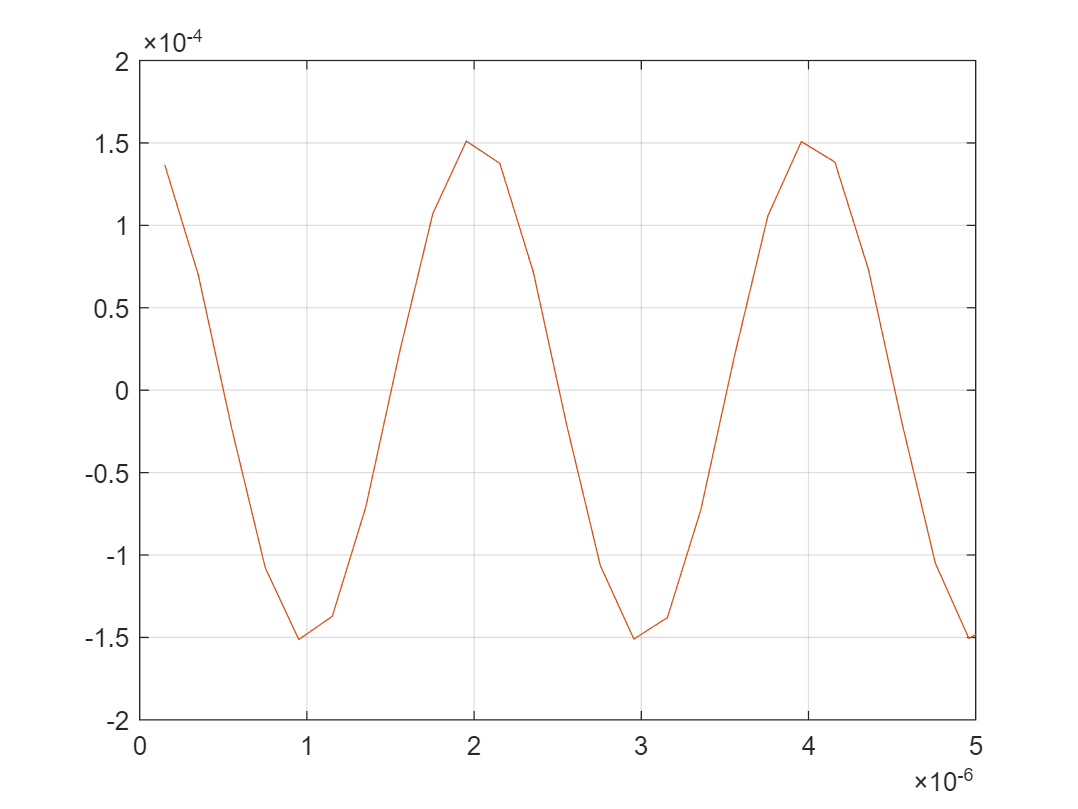

%% /////////////////////// Build delta Id ///////////////////////////////
t = linspace(timeoffset,51/Fin + timeoffset,512);
I_mag = [-79.2986, -155.849, -149.203];
COS = [cos(win.*t); cos(2*win.*t); cos(3*win.*t)];
Id = sqrt(2)*db2mag(I_mag) * COS;
Iref = sqrt(2)*db2mag(-79.2979)*COS(1,:);
I_delta_mag = [-128.79, -155.89, -149.25];
delta_Id = sqrt(2)*db2mag(I_delta_mag) * COS;
figure()
plot(t, [Id; Iref]);
grid on;
xlim([0, 5e-6])

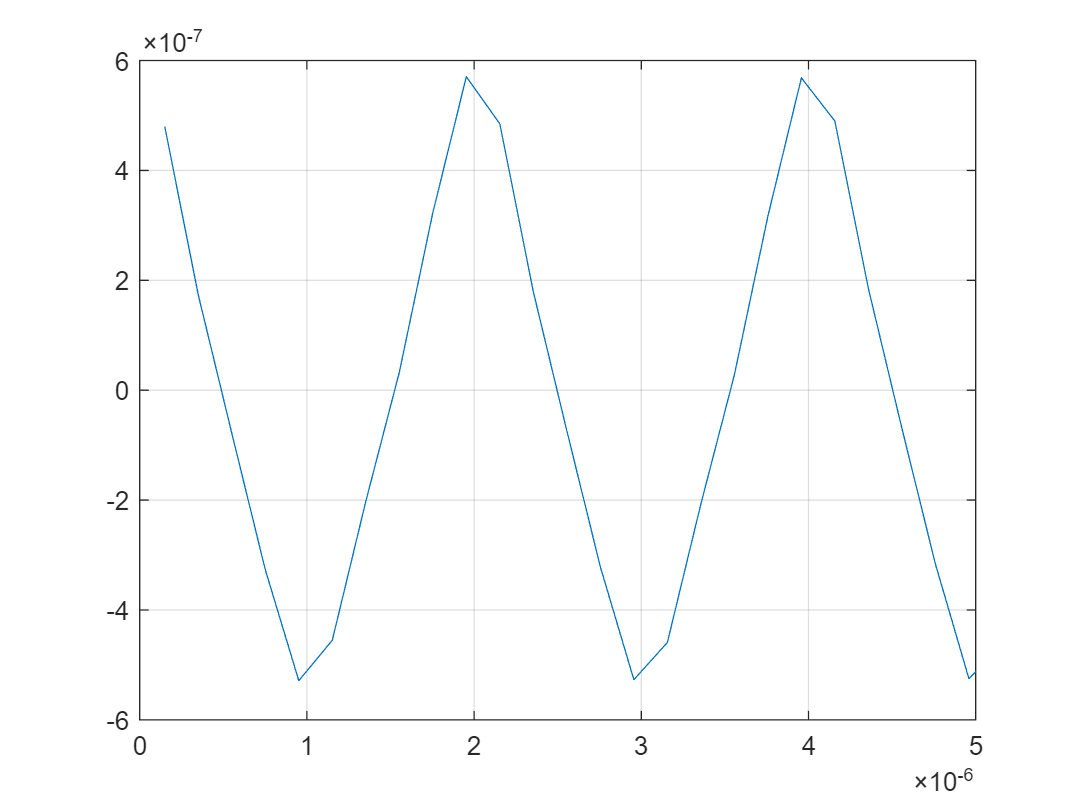

figure()
plot(t, delta_Id);
grid on;
xlim([0, 5e-6])

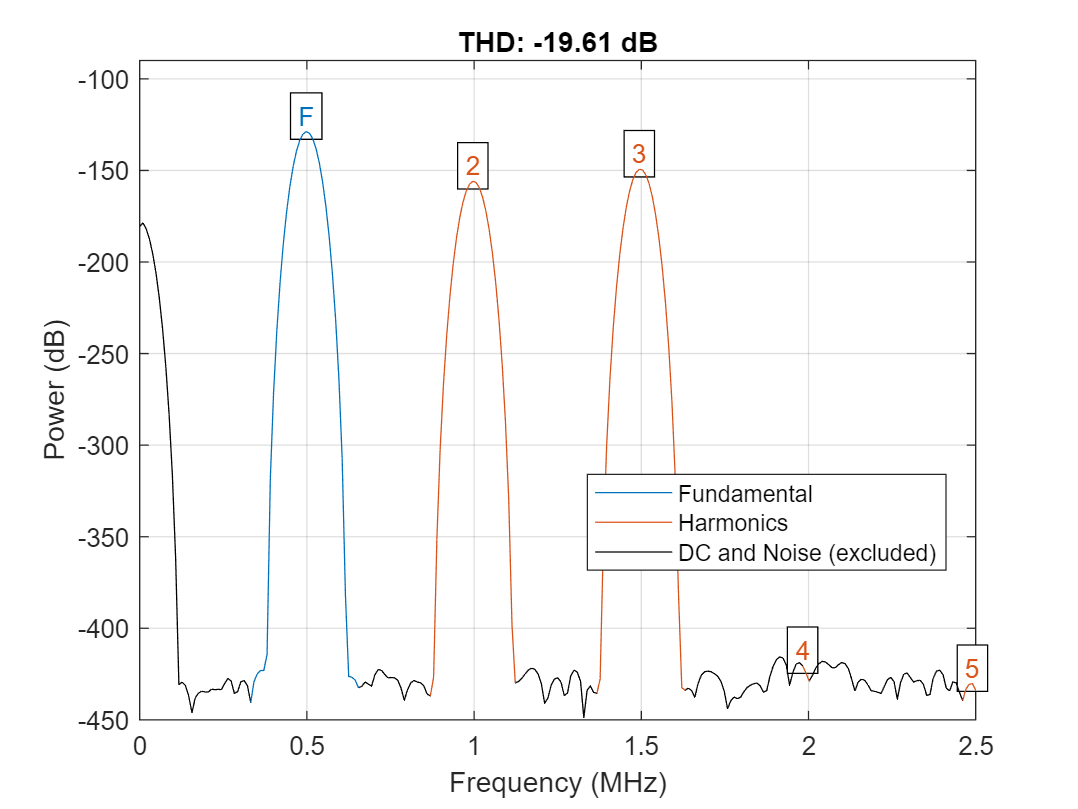

ans = -19.6079

thd(delta_Id, Fs)